% =========================================================================
% PROGETTO: ANC - Digital Twin con Sorgente in Movimento
% SCRIPT: Testbench Ingegneristico per Moving Jackhammer
% =========================================================================

clear; clc; close all;

%% 1. Configurazione Parametri
Fs = 48000;              % Alta fedeltà per campionare il jitter
T = 10;                   % 4 secondi di simulazione
N_samples = T * Fs;
t = (0:N_samples-1)' / Fs;

%% 2. Generazione Digital Twin (Sorgente in Movimento)
disp('Generazione rumore complesso: Martello in movimento...');

Generazione rumore complesso: Martello in movimento...



gen = AdvancedSoundGenerator();

% Definiamo una traiettoria: il martello parte lontano e si avvicina
opts.startPos = [3, 8];  % 3m davanti, 8m a sinistra
opts.endPos   = [0.5, 0];% Finisce a 50cm, dritto davanti
opts.bpm = 480;
opts.jitterStd = 0.1;    % Jitter cattivo per mandare in crisi il filtro

% x: Segnale al microfono di riferimento (vicino al martello)
% d: Segnale captato all'ascoltatore (0,0) con ritardo variabile e ISO 9613
[x, d, ~] = gen.MovingJackhammer(T, Fs, opts);

% Allineamento lunghezze
minL = min([length(x), length(d), N_samples]);
x = x(1:minL); d = d(1:minL); t = t(1:minL);

%% 3. Inizializzazione ANC (Standard LMS)
disp('Inizializzazione DSP Adattivo...');

Inizializzazione DSP Adattivo...



% N_taps deve coprire la distanza massima (sqrt(3^2 + 8^2) = 8.5m)
% 8.5m / 343m/s * 48000Hz = ~1200 campioni.
N_taps = 1500;       
mu = 0.6;            % Learning rate per inseguimento dinamico
useNLMS = true;

anc_filter = AdaptiveLMSFilter(N_taps, mu, useNLMS);

%% 4. Loop Real-Time (Hardware Emulation)
disp('Esecuzione Loop ANC...');

Esecuzione Loop ANC...



y = zeros(minL, 1);
e = zeros(minL, 1);

tic;
for n = 1:minL
    % Il filtro riceve il riferimento x e cerca di minimizzare l'errore e
    [y(n), e(n)] = anc_filter.step(x(n), d(n));
end
toc;

Elapsed time is 1.000530 seconds.



%% 5. Analisi Performance e Dashboard
disp('Rendering Dashboard...');

Rendering Dashboard...


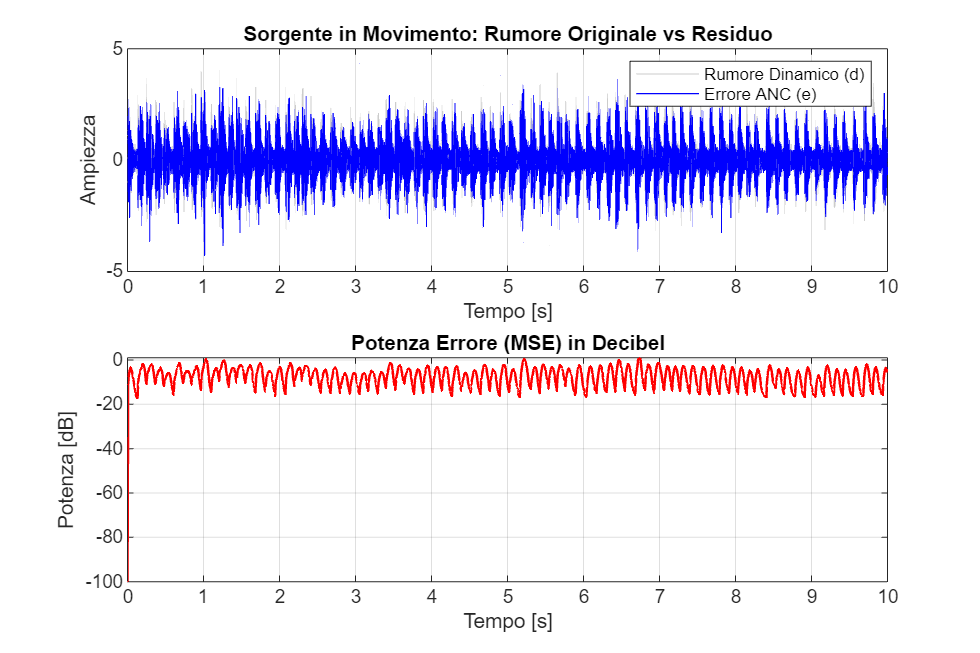


window_size = round(Fs * 0.04);
mse_dB = 10 * log10(filter(ones(window_size,1)/window_size, 1, e.^2) + 1e-10);

figure('Name', 'ANC Dynamic Stress Test', 'Position', [100 100 1200 800], 'Color', 'w');

% Plot 1: Analisi Temporale
subplot(2,1,1);
plot(t, d, 'Color', [0.8 0.8 0.8]); hold on;
plot(t, e, 'b', 'LineWidth', 0.6);
title('Sorgente in Movimento: Rumore Originale vs Residuo');
xlabel('Tempo [s]'); ylabel('Ampiezza');
legend('Rumore Dinamico (d)', 'Errore ANC (e)');
grid on;

% Plot 2: Learning Curve Dinamica
subplot(2,1,2);
plot(t, mse_dB, 'r', 'LineWidth', 1.2);
title('Potenza Errore (MSE) in Decibel');
xlabel('Tempo [s]'); ylabel('Potenza [dB]');
grid on;


% Calcolo attenuazione finale (media dell'ultimo secondo)
att_finale = 10*log10(mean(d(end-Fs:end).^2)) - 10*log10(mean(e(end-Fs:end).^2));
fprintf('Attenuazione media a fine traiettoria: %.2f dB\n', att_finale);

Attenuazione media a fine traiettoria: 1.25 dB



%% 6. Prova Audio (Fondamentale)
disp('Ascolto: Rumore in movimento (Originale)...');

Ascolto: Rumore in movimento (Originale)...


soundsc(d, Fs);
pause(T + 1);

disp('Ascolto: Risultato ANC (Noterai il tracking dell''algoritmo)...');

Ascolto: Risultato ANC (Noterai il tracking dell'algoritmo)...


soundsc(e, Fs);